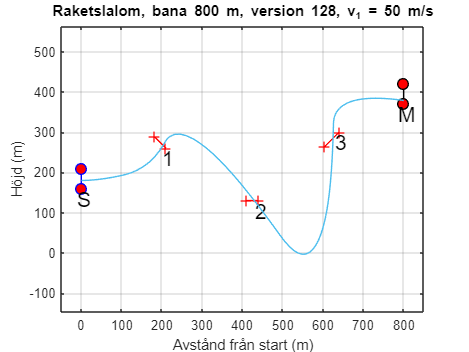

clear
clf
load bana800-128.mat;
tspan = [0,26.05];
begin=[0,50,180,0];
[t,y]= ode45(@MP3funk,tspan,begin);
plotTrack(portx,porty,ver,v1);
hold on;
plot(y(:,1),y(:,3));
hold off;

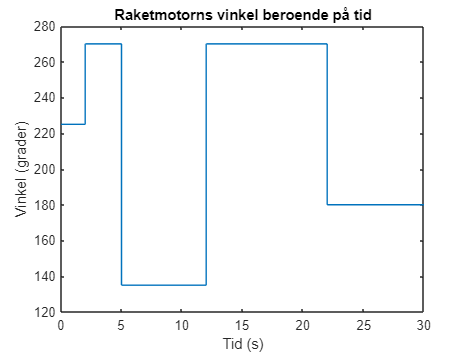

t_v = [0,2,2,5,5,12,12,22,22,30];
v_v = [rad2deg(5*pi/4),rad2deg(5*pi/4),rad2deg(3*pi/2),rad2deg(3*pi/2),rad2deg(3*pi/4),rad2deg(3*pi/4), rad2deg(3*pi/2),rad2deg(3*pi/2),rad2deg(pi),rad2deg(pi)];
plot(t_v,v_v)

xlabel('Tid (s)')
ylabel('Vinkel (grader)')
title('Raketmotorns vinkel beroende på tid')
axis on;

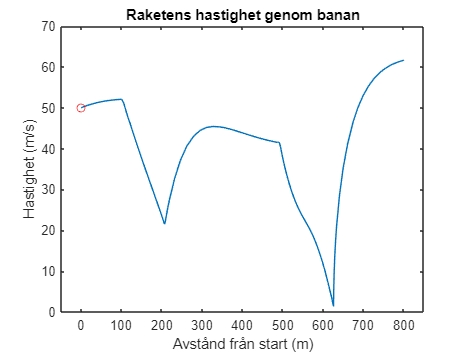


plot(y(:,1),y(:,2));
hold on;
plot(0,50,'or')
xlabel('Avstånd från start (m)')
ylabel('Hastighet (m/s)')
title(['Raketens hastighet genom banan'])
xlim([-50,850]);